clear all
clc

## 2. Background

### 2.1 Data format/representaion

Train dataset contains X (patterns) and T(labels). They should be shown as matrix in Matlab, e.g.,

X=[ -1, 1,-1,1;-1,-1,1,1]

X =     -1     1    -1     1
    -1    -1     1     1



T = [-1,1,1,-1]

T =     -1     1     1    -1


It contains two types of label (-1 and 1; but 0 and 1 is also fine)

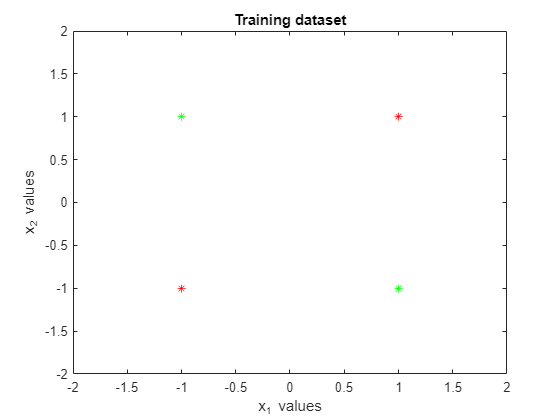

% TODO, convert X,T to X_1 and X_2 so that we can plot them
data_positive =[];
data_negative =[];
for index=1:length(T)
    if T(index)<0
        data_positive = [data_positive, X(:,index)];
    else
        data_negative = [data_negative, X(:,index)];
    end
end
data_positive;
data_negative;

figure;  


pos_x1=data_positive(1,:);
pos_x2=data_positive(2,:);
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1=data_negative(1,:);
neg_x2=data_negative(2,:);
plot(neg_x1,neg_x2,"g*")

xlim([-2,2])
ylim([-2,2])
title('Training dataset') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

But note, this is a XOR problem which not be sloved by one seperation line (single layer perceptron)

For TLU(threshold logic unit), we need to extend X matrix to show threshold in a compact way. (T matix is not afftected)

X_extend=[ X ; ones(1,4)];
T;

The weight matrix will be trained with above train dataset.  But we can know the size of W matrix now, and the relation btw X_e, W and T.

W_init=randn(1,3)

W_init =    -1.0582   -0.4686   -0.2725


We want to have below eqation after training


$$T\approx W*X_{\textrm{extend}}$$


But below is the first step

W_init*X_extend 

ans =     1.2543   -0.8620    0.3171   -1.7993


The classfication system can be shown as 

y=W*x_extend

### 2.2 Delta rule

Note: η (eta) is the learning rate, in the code we will use eta in stead.

The learning (updating weight) for one epoch need below equation


$$\Delta W=-\eta \;\left(W\;X-T\right)\;X^T$$


We can show it in the code

eta = 0.001

eta = 1.0000e-03


delta_W = - eta* (W_init*X_extend-T)*X_extend'

delta_W =     0.0042    0.0019    0.0011



W_new = W_init + delta_W

W_new =    -1.0539   -0.4667   -0.2714


2.3 Evaluation

For single layer, we can show the seperation line.

figure;  

plot(pos_x1,pos_x2,"r*")
hold on
plot(neg_x1,neg_x2,"g*")
hold on

W = W_init % to show seperation line for W_init

W =    -1.0582   -0.4686   -0.2725


x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);  % x1*w1 + x2*w2 + w3 =0
plot(x_1,x_2,'g-') % line in green color

hold on

W = W_new % to show seperation line for W_new (after one epoch)

W =    -1.0539   -0.4667   -0.2714


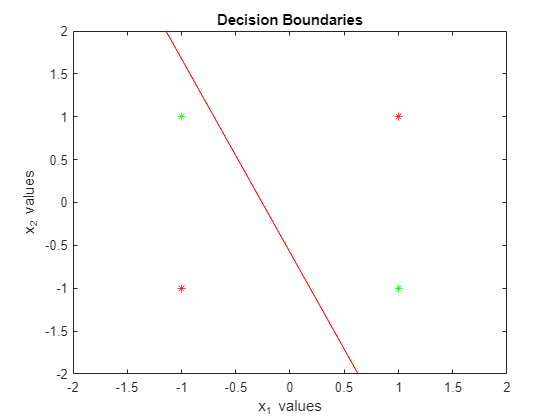

x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'r-') % new line in red color

title('Decision Boundaries') 
xlim([-2,2])
ylim([-2,2])
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label

For multi-layer perceprons, seperation (hyper-)plane might not be visible.

In that case, we need to show the error over epochs

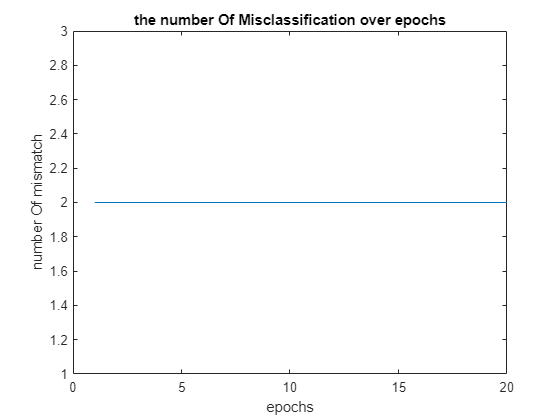

% XOR 
epoch = 20;
mismatch= zeros(1,epoch);
W = W_init;
eta = 0.1;

for index=1:epoch
    delta_W = - eta* (W*X_extend-T)*X_extend';
    W = W + delta_W;
    mismatch(1,index)=numberOfMisclassification(W, X_extend, T);
end

figure
plot(mismatch)
title('the number Of Misclassification over epochs') 
xlabel('epochs') % x-axis label
ylabel('number Of mismatch') % y-axis label

For XOR problem, we cannot see the progress. 

But let's try with OR problem.

% OR
T = [-1     1     1    1]

T =     -1     1     1     1


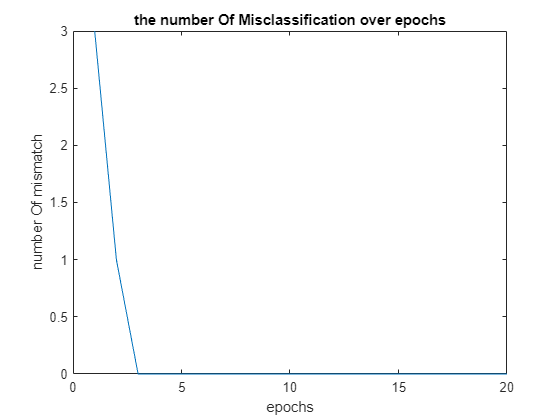

epoch = 20;
mismatch= zeros(1,epoch);
W = W_init;
eta = 0.1;

for index=1:epoch
    delta_W = - eta* (W*X_extend-T)*X_extend';
    W = W + delta_W;
    mismatch(1,index)=numberOfMisclassification(W, X_extend, T);
end

figure
plot(mismatch)
title('the number Of Misclassification over epochs') 
xlabel('epochs') % x-axis label
ylabel('number Of mismatch') % y-axis label

More details, try to use delta_rule_batch() function

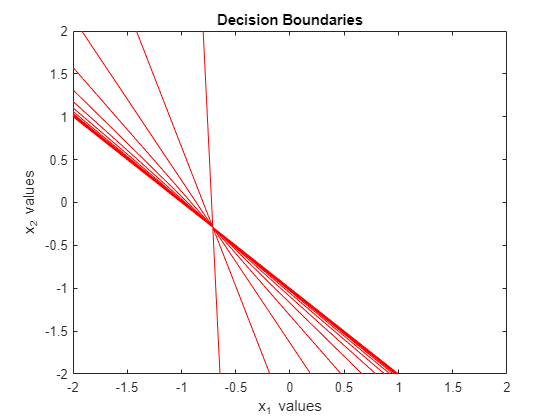

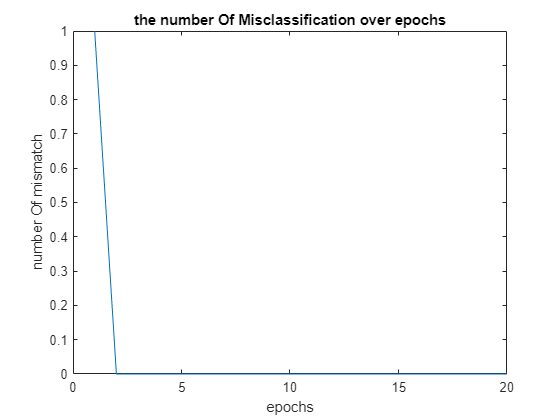

W =     0.5000    0.5000    0.5000


W = delta_rule_batch(X, T, epoch)

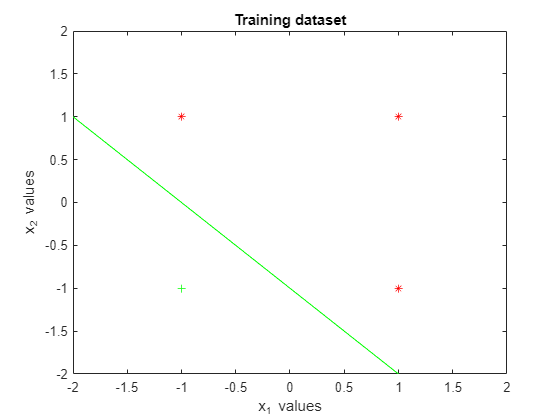


figure 
pos_x1 = [-1,1, 1];
pos_x2 = [1,-1, 1];
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1 =[-1];
neg_x2 =[-1];
plot(neg_x1,neg_x2,"g+")
hold on


x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);  % x1*w1 + x2*w2 + w3 =0
plot(x_1,x_2,'g-') % line in green color

xlim([-2,2])
ylim([-2,2])
title('Training dataset') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on